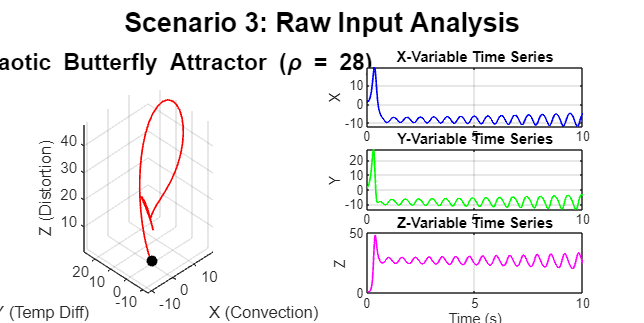


% LORENZ SCENARIO 3: CHAOTIC REGIME (N=1000 | 15 TERMS)

clear; clc; close all;

% 1. DATA GENERATION 
sigma = 10; rho = 28; beta = 8/3;
t_max = 10; 
num_points = 1000; 
t_raw = linspace(0, t_max, num_points); 

lorenz_odes = @(t, s) [sigma*(s(2)-s(1)); s(1)*(rho-s(3))-s(2); s(1)*s(2)-beta*s(3)];
[t_solve, states] = ode45(lorenz_odes, t_raw, [1; 1; 1]);




t_1000 = linspace(0, t_max, num_points);
x = interp1(t_solve, states(:,1), t_1000)';
y = interp1(t_solve, states(:,2), t_1000)';
z = interp1(t_solve, states(:,3), t_1000)';


% 1B. RAW DATA 

figure('Name', 'Scenario 3: Raw Chaotic Input', 'Color', 'w', 'Position', [50, 50, 1200, 600]);

% Left Panel: The 3D Attractor
subplot(1, 2, 1);
plot3(x, y, z, 'r', 'LineWidth', 1); hold on;
plot3(x(1), y(1), z(1), 'ko', 'MarkerFaceColor', 'k'); % Start point
grid on; axis tight;
xlabel('X (Convection)'); ylabel('Y (Temp Diff)'); zlabel('Z (Distortion)');
title('3D Chaotic Butterfly Attractor (\rho = 28)', 'FontSize', 14);
view(-45, 25);

% Right Panel: Individual Time Series
subplot(3, 2, 2);
plot(t_1000, x, 'b', 'LineWidth', 1);
title('X-Variable Time Series'); grid on; ylabel('X');

subplot(3, 2, 4);
plot(t_1000, y, 'g', 'LineWidth', 1);
title('Y-Variable Time Series'); grid on; ylabel('Y');

subplot(3, 2, 6);
plot(t_1000, z, 'm', 'LineWidth', 1);
title('Z-Variable Time Series'); grid on; ylabel('Z');
xlabel('Time (s)');

sgtitle('Scenario 3: Raw Input Analysis', 'FontSize', 16, 'FontWeight', 'bold');

% 2. KOOPMAN LIFTING: 15-VARIABLE DICTIONARY
mu_x = mean(x); std_x = std(x); nx = (x - mu_x)/std_x;
mu_y = mean(y); std_y = std(y); ny = (y - mu_y)/std_y;
mu_z = mean(z); std_z = std(z); nz = (z - mu_z)/std_z;

% Dictionary: Linear, Quadratic, Cross-Terms, and Cubic
Lifted = [nx'; ny'; nz'; ...                 
          nx'.^2; ny'.^2; nz'.^2; ...         
          nx'.*ny'; nx'.*nz'; ny'.*nz'; ...   
          nx'.^3; ny'.^3; nz'.^3; ...         
          (nx'.^2).*ny'; (nx'.^2).*nz'; (ny'.^2).*nz']; 

% 3. HANKELIZATION
L = 40; 
num_vars = size(Lifted, 1); 
N = length(nx); K = N - L + 1;
H = zeros(num_vars * L, K);
for k = 1:K, window = Lifted(:, k:k+L-1); H(:, k) = window(:); end

% 4. DMD & FORECAST (80% Training for better stability)
train_cols = floor(K * 0.4); 
X = H(:, 1:train_cols-1); X_prime = H(:, 2:train_cols);

[U, S, V] = svd(X, 'econ');
r = 60; 
Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);

A_tilde = (Ur') * X_prime * Vr / Sr;
[W, D] = eig(A_tilde); lambdas = diag(D);
Phi = X_prime * Vr / Sr * W; 
b = Phi \ X(:, 1);           

time_dynamics = zeros(r, K);
for step = 0:K-1, time_dynamics(:, step+1) = (b .* (lambdas .^ step)); end
signal_forecast_norm = real(Phi * time_dynamics);

% 5. UN-NORMALIZE
pred_x = (signal_forecast_norm(1,:) .* std_x) + mu_x;
pred_y = (signal_forecast_norm(2,:) .* std_y) + mu_y;
pred_z = (signal_forecast_norm(3,:) .* std_z) + mu_z;
truth_x = (H(1,:) .* std_x) + mu_x;

rmse_val = sqrt(mean((truth_x(train_cols+1:end) - pred_x(train_cols+1:end)).^2));

% 6. RESULTS CONSOLE


disp('   SCENARIO 3: CHAOTIC REGIME (1000 POINTS)    ');

   SCENARIO 3: CHAOTIC REGIME (1000 POINTS)    


fprintf('Matrix Rows (num_vars * L): %d\n', size(H,1));

Matrix Rows (num_vars * L): 600


fprintf('Matrix Columns (K):         %d\n', K);

Matrix Columns (K):         961


fprintf('Training Points:            %d\n', train_cols);

Training Points:            384


fprintf('Forecasted Points:          %d\n', K - train_cols);

Forecasted Points:          577


fprintf('RMSE:                       %.6f\n', rmse_val);

RMSE:                       0.739066


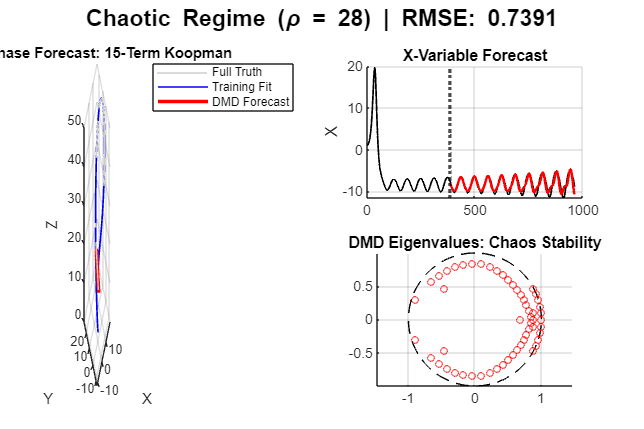


% 7. DASHBOARD VISUALIZATION
figure('Name', 'Chaos Forecast (15 Terms)', 'Color', 'w', 'Position', [100, 100, 1200, 800]);

% A. 3D Phase Attractor 
subplot(2, 2, [1, 3]); 
plot3(x, y, z, 'Color', [0.8 0.8 0.8], 'LineWidth', 0.5); hold on;
plot3(pred_x(1:train_cols), pred_y(1:train_cols), pred_z(1:train_cols), 'b-', 'LineWidth', 1);
plot3(pred_x(train_cols+1:end), pred_y(train_cols+1:end), pred_z(train_cols+1:end), 'r-', 'LineWidth', 2);
grid on; view(-45, 25);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D Phase Forecast: 15-Term Koopman');
legend('Full Truth', 'Training Fit', 'DMD Forecast');

% B. X-Variable Time Series
subplot(2, 2, 2); hold on;
plot(1:K, truth_x, 'k', 'LineWidth', 1);
plot(train_cols+1:K, pred_x(train_cols+1:end), 'r', 'LineWidth', 1.5);
xline(train_cols, 'k:', 'LineWidth', 2); 
title('X-Variable Forecast'); grid on; ylabel('X');

% C. DMD Eigenvalues
subplot(2, 2, 4); hold on;
th = linspace(0,2*pi,100); plot(cos(th), sin(th), 'k--');
plot(real(lambdas), imag(lambdas), 'ro', 'MarkerSize', 4);
title('DMD Eigenvalues: Chaos Stability'); 
grid on; axis equal;

sgtitle(['Chaotic Regime (\rho = 28) | RMSE: ', num2str(rmse_val, '%.4f')], 'FontWeight', 'bold');